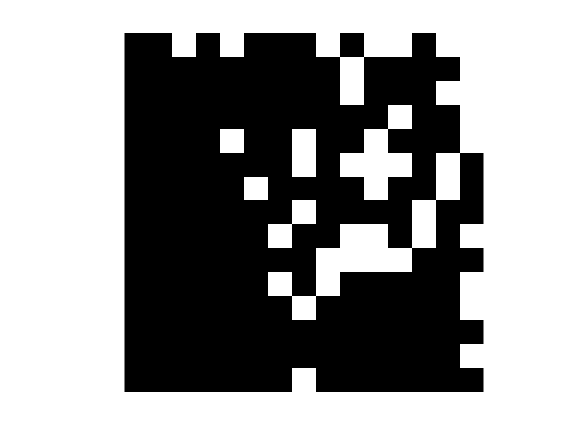

%grid size
m = 15; 
n = 15;
%Adding Random squares to the plot
[X,Y] = meshgrid(1:m,1:n);  
Z = 255*ones(m,n);
idx = randperm(m*n,100);  
Z(idx) = 0;  
%pcolor(X,Y,Z)
im = imshow(Z,"InitialMagnification","fit");
im.ButtonDownFcn = @changeColor;
grid on

function [x,y] = changeColor(obj,ev)

x = ev.IntersectionPoint(1);
y = ev.IntersectionPoint(2);


m = ceil(y);
n = ceil(x);

%Makes the Values black
obj.CData(m,n) = 0;

%Prints to show it was clicked on
disp('click')
                    

% Assign the updated board into base workspace 
% so it is accessible from elsewhere in the script
assignin("caller","newBoard",obj.CData)
end 